# **Cash-or-Nothing Call Option with P1 and P2**

## **Parameters:**

% Parameters for Black-Scholes Equation: 
E = 1;
A = 2;
r = 0.05;
sigma = 0.2;
T = 1; 
L = 10;

% Parameters for Gauss-Seidel:
max_iter = 100000;
allowed_error = 0.0001;

% Parameters for Spacial Mesh:
number_of_the_elements_space = L;
start_of_the_interval_space = 0;
end_of_the_interval_space = A;

% Parameters related to Time Integration:
number_of_the_elements_time = L;
start_of_the_interval_time = 0;
end_of_the_interval_time = T;
delta_time = (end_of_the_interval_time - start_of_the_interval_time) / number_of_the_elements_time;

% Parameters related to Euler Method:
theta = 1 / 2;

## **Analytical Solution of Cash-or-nothing Call option: **

U_exact = cash_or_nothing_call_analytical(E, A, r, sigma, T, L);

## Black-Scholes Equation for the Approximation:


$$\frac{\partial }{\partial \tau }V-\frac{1}{2}\sigma^2 \frac{\partial^2 }{\partial x^2 }V+\left(\frac{\sigma^2 }{2}-r\right)\frac{\partial }{\partial x}V+\textrm{rV}=0$$



$$\frac{\partial }{\partial \tau }V=\frac{1}{2}\sigma^2 \frac{\partial^2 }{\partial x^2 }V-\left(\frac{\sigma^2 }{2}-r\right)\frac{\partial }{\partial x}V-\textrm{rV}$$



$$\begin{array}{l}
x=\ln \left(\frac{S}{E}\right)\\
\tau =T-t\\
k=\frac{\sigma^2 }{2}
\end{array}$$


k = sigma ^ 2 / 2;

start_tau = T - start_of_the_interval_time;
end_tau = T - end_of_the_interval_time;
delta_tau = (end_tau - start_tau) / number_of_the_elements_time;

## Galerkin Method for Black-Scholes Equation:


$$\frac{\partial }{\partial \tau }\left(\textrm{Mu}\right)=-k*\textrm{Ku}-\left(k-r\right)\textrm{Nu}-\textrm{rMu}$$


# **P1 Approximation of Cash-or-Nothing Call Option**

### Variables/Matrices for P1:

% Variables for P1:
number_of_nodes_p1 = number_of_the_elements_space + 1;
start_x = log(start_of_the_interval_space + 1e-10);
end_x = log(end_of_the_interval_space);

S_values = linspace(start_of_the_interval_space, end_of_the_interval_space, number_of_nodes_p1);

% Matrices for P1:
K_P1 = stiffness_matrix_p1(number_of_the_elements_space, start_of_the_interval_space, end_of_the_interval_space);
M_P1 = mass_matrix_p1(number_of_the_elements_space, start_of_the_interval_space, end_of_the_interval_space);
N_P1 = convection_matrix_p1(number_of_the_elements_space);

% Variables for boundary conditions:
K_21_P1 = K_P1(2, 1);
K_EE_P1 = K_P1(end - 1, end);
 
M_21_P1 = M_P1(2, 1);
M_EE_P1 = M_P1(end - 1, end);

N_21_P1 = N_P1(2, 1);
N_EE_P1 = N_P1(end - 1, end);
 
% Updating Matrices for P1:
M_P1(1, :) = [];
M_P1(end, :) = [];
M_P1(:, 1) = [];
M_P1(:, end) = [];
 
K_P1(1, :) = [];
K_P1(end, :) = [];
K_P1(:, 1) = [];
K_P1(:, end) = [];

N_P1(1, :) = [];
N_P1(end, :) = [];
N_P1(:, 1) = [];
N_P1(:, end) = [];

K_P1 = full(K_P1);
N_P1 = full(N_P1);
M_P1 = full(M_P1);

## Euler Method for Galerkin Method:

#### Necessary Variables:

U_P1 = zeros(number_of_nodes_p1, number_of_the_elements_time + 1);
 
u_xsts1 = pay_off(S_values(1), A, E);
u_xstmid1 = pay_off(S_values(2 : end - 1), A, E);
u_xste1 = pay_off(S_values(end), A, E);
 
U_P1(:, end) = [u_xsts1(:); u_xstmid1(:); u_xste1(:)];

U_Past1 = U_P1(2 : end - 1, end);

% Boundary Contribution Vectors (Stiffness Matrix):
B_K_Past1 = zeros(number_of_nodes_p1 - 2, 1);
B_K_Present1 = zeros(number_of_nodes_p1 - 2, 1);

B_K_Past1(1, 1) = u_xsts1 * K_21_P1;
B_K_Past1(end, 1) = u_xste1 * K_EE_P1;

% Boundary Contribution Vectors (Mass Matrix):
B_M_Past1 = zeros(number_of_nodes_p1 - 2, 1);
B_M_Present1 = zeros(number_of_nodes_p1 - 2, 1);

B_M_Past1(1, 1) = u_xsts1 * M_21_P1;
B_M_Past1(end, 1) = u_xste1 * M_EE_P1;

% Boundary Contribution Vectors (Convection Matrix):
B_N_Past1 = zeros(number_of_nodes_p1 - 2, 1);
B_N_Present1 = zeros(number_of_nodes_p1 - 2, 1);

B_N_Past1(1, 1) = u_xsts1 * N_21_P1;
B_N_Past1(end, 1) = u_xste1 * N_EE_P1;


tic;
% Finding Unknowns for eaxh Time-step: 
for i = 1 : number_of_the_elements_time
 

     % Boundary Condition at present step:
     U_at_xmin = 0;
     current_time = T - i * delta_time;
     U_at_xmax = A * exp(-r * (T - current_time));
    
     % Boundary Contribution at Present Time(Stiffness Matrix):
     B_K_Present1(1, 1) = U_at_xmin * K_21_P1;
     B_K_Present1(end, 1) = U_at_xmax * K_EE_P1;
    
     % Boundary Contribution at Present Time(Mass Matrix):
     B_M_Present1(1, 1) = U_at_xmin * M_21_P1;
     B_M_Present1(end, 1) =  U_at_xmax * M_EE_P1;

     % Boundary Contribution at Present Time(Convection Matrix):
     B_N_Present1(1, 1) = U_at_xmin * N_21_P1;
     B_N_Present1(end, 1) =  U_at_xmax * N_EE_P1;

     
     LHS = M_P1 - theta * delta_time * (- k * K_P1 - (k - r) * N_P1 - r * M_P1);
    
     RHS = M_P1 * U_Past1 + B_M_Past1 - B_M_Present1 + ...
         + delta_time * theta * (- k * B_K_Present1 - (k - r) * B_N_Present1 - r * B_M_Present1) ...
         + delta_time * (1 - theta) * (-k * K_P1 * U_Past1 - (k - r) * N_P1 * U_Past1 - r * M_P1 * U_Past1) ...
         + delta_time * (1 - theta) * (-k * B_K_Past1 - (k - r) * B_N_Past1 - r * B_M_Past1);
 
     B_K_Past1(1, 1) = U_at_xmin * K_21_P1;
     B_K_Past1(end, 1) = U_at_xmax * K_EE_P1;
    
     B_M_Past1(1, 1) = U_at_xmin * M_21_P1;
     B_M_Past1(end, 1) = U_at_xmax * M_EE_P1;
 
     B_N_Past1(1, 1) = U_at_xmin * N_21_P1;
     B_N_Past1(end, 1) = U_at_xmax * N_EE_P1;

     ANS = LHS \ RHS;

     U_Past1 = ANS;
 
     U_P1(1, end - i) = U_at_xmin ;
     U_P1(2 : end - 1, end - i) = ANS;
     U_P1(end, end - i) = U_at_xmax ;

end 
toc;

Elapsed time is 0.183779 seconds.


## Plotting P1:

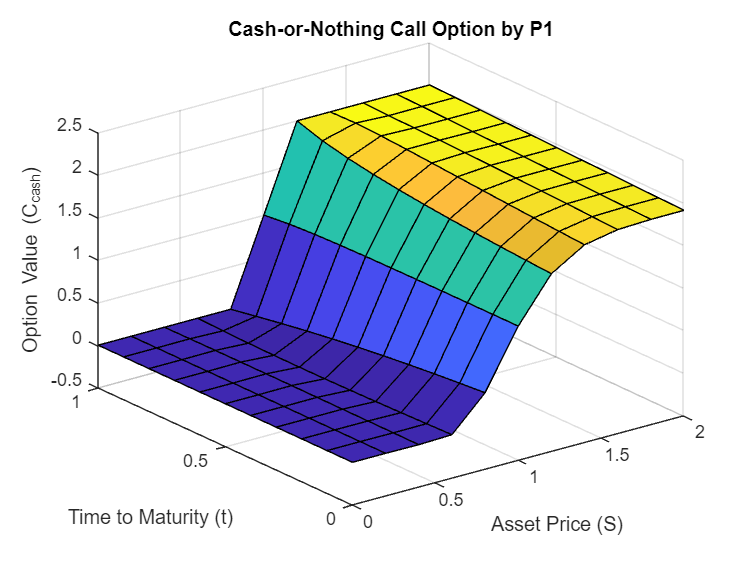

x_p1_values = linspace(start_of_the_interval_space, end_of_the_interval_space, number_of_nodes_p1);
t_values = linspace(start_of_the_interval_time, end_of_the_interval_time, number_of_the_elements_time + 1);
[X_P1, T_P1] = meshgrid(x_p1_values, t_values);

figure
surf(X_P1, T_P1, U_P1')
xlabel('Asset Price (S)')
ylabel('Time to Maturity (t)')
zlabel('Option Value (C_{cash})')
title('Cash-or-Nothing Call Option by P1')

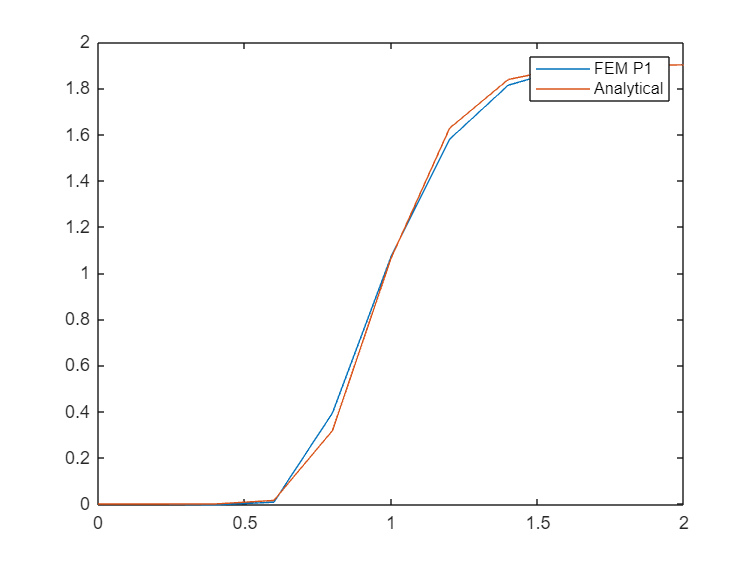

figure;
plot(S_values, U_P1(:, 1));
hold on;
plot(S_values, U_exact(1, :));
hold off;

legend('FEM P1', 'Analytical');

# **P2 Approximation of Cash-or-Nothing Call Option**

### Variables/Matrices for P2:

% Variables for P2:
number_of_nodes_p2 = 2 * number_of_the_elements_space + 1;

nodes_p1 = linspace(start_x, end_x, number_of_nodes_p2);
S_values = linspace(start_of_the_interval_space, end_of_the_interval_space, number_of_nodes_p2);

% Matrices for P2:
K_P2 = stiffness_matrix_p2(number_of_the_elements_space, start_of_the_interval_space, end_of_the_interval_space);
M_P2 = mass_matrix_p2(number_of_the_elements_space, start_of_the_interval_space, end_of_the_interval_space);
N_P2 = convection_matrix_p2(number_of_the_elements_space, start_of_the_interval_space, end_of_the_interval_space);

% Variables for boundary conditions:
K_21_P2 = K_P2(2, 1);
K_31_P2 = K_P2(3, 1);
K_PE_P2 = K_P2(end - 2, end);
K_EE_P2 = K_P2(end - 1, end);
 
M_21_P2 = M_P2(2, 1);
M_31_P2 = M_P2(3, 1);
M_PE_P2 = M_P2(end - 2, end);
M_EE_P2 = M_P2(end - 1, end);

N_21_P2 = N_P2(2, 1);
N_31_P2 = N_P2(3, 1);
N_PE_P2 = N_P2(end - 2, end);
N_EE_P2 = N_P2(end - 1, end);
 
% Updating Matrices for P2:
M_P2(1, :) = [];
M_P2(end, :) = [];
M_P2(:, 1) = [];
M_P2(:, end) = [];
 
K_P2(1, :) = [];
K_P2(end, :) = [];
K_P2(:, 1) = [];
K_P2(:, end) = [];

N_P2(1, :) = [];
N_P2(end, :) = [];
N_P2(:, 1) = [];
N_P2(:, end) = [];

K_P2 = full(K_P2);
N_P2 = full(N_P2);
M_P2 = full(M_P2);

## Euler Method for Galerkin Method:

#### Necessary Variables:

U_P2 = zeros(number_of_nodes_p2, number_of_the_elements_time + 1);

S_values2 = linspace(start_of_the_interval_space, end_of_the_interval_space, number_of_nodes_p2);

u_xsts2 = pay_off(S_values2(1), A, E);
u_xstmid2 = pay_off(S_values2(2 : end - 1), A, E);
u_xste2 = pay_off(S_values2(end), A, E);
 
U_P2(:, end) = [u_xsts2(:); u_xstmid2(:); u_xste2(:)];

U_Past2 = U_P2(2 : end - 1, end);

% Boundary Contribution Vectors (Stiffness Matrix):
B_K_Past2 = zeros(number_of_nodes_p2 - 2, 1);
B_K_Present2 = zeros(number_of_nodes_p2 - 2, 1);

B_K_Past2(1, 1) = u_xsts2 * K_21_P2;
B_K_Past2(2, 1) = u_xsts2 * K_31_P2;
B_K_Past2(end - 1, 1) = u_xste2 * K_PE_P2;
B_K_Past2(end, 1) = u_xste2 * K_EE_P2;

% Boundary Contribution Vectors (Mass Matrix):
B_M_Past2 = zeros(number_of_nodes_p2 - 2, 1);
B_M_Present2 = zeros(number_of_nodes_p2 - 2, 1);

B_M_Past2(1, 1) = u_xsts2 * M_21_P2;
B_M_Past2(2, 1) = u_xsts2 * M_31_P2;
B_M_Past2(end - 1, 1) = u_xste2 * M_PE_P2;
B_M_Past2(end, 1) = u_xste2 * M_EE_P2;

% Boundary Contribution Vectors (Convection Matrix):
B_N_Past2 = zeros(number_of_nodes_p2 - 2, 1);
B_N_Present2 = zeros(number_of_nodes_p2 - 2, 1);

B_N_Past2(1, 1) = u_xsts2 * N_21_P2;
B_N_Past2(2, 1) = u_xsts2 * N_31_P2;
B_N_Past2(end - 1, 1) = u_xste2 * N_PE_P2;
B_N_Past2(end, 1) = u_xste2 * N_EE_P2;


tic;
% Finding Unknowns for eaxh Time-step: 
for i = 1 : number_of_the_elements_time
 

     % Boundary Condition at present step:
     U_at_xmin = 0;
     current_time = T - i * delta_time;
     U_at_xmax = A * exp(-r * (T - current_time));
    
     % Boundary Contribution at Present Time(Stiffness Matrix):
     B_K_Present2(1, 1) = U_at_xmin * K_21_P2;
     B_K_Present2(2, 1) = U_at_xmin * K_31_P2;
     B_K_Present2(end - 1, 1) = U_at_xmax * K_PE_P2;
     B_K_Present2(end, 1) = U_at_xmax * K_EE_P2;
    
     % Boundary Contribution at Present Time(Mass Matrix):
     B_M_Present2(1, 1) = U_at_xmin * M_21_P2;
     B_M_Present2(2, 1) = U_at_xmin * M_31_P2;
     B_M_Present2(end - 1, 1) = U_at_xmax * M_PE_P2;
     B_M_Present2(end, 1) =  U_at_xmax * M_EE_P2;

     % Boundary Contribution at Present Time(Convection Matrix):
     B_N_Present2(1, 1) = U_at_xmin * N_21_P2;
     B_N_Present2(2, 1) = U_at_xmin * N_31_P2;
     B_N_Present2(end - 1, 1) = U_at_xmax * N_PE_P2;
     B_N_Present2(end, 1) =  U_at_xmax * N_EE_P2;

     
     LHS = M_P2 - theta * delta_time * (- k * K_P2 - (k - r) * N_P2 - r * M_P2);
    
     RHS = M_P2 * U_Past2 + B_M_Past2 - B_M_Present2 + ...
         + delta_time * theta * (- k * B_K_Present2 - (k - r) * B_N_Present2 - r * B_M_Present2) ...
         + delta_time * (1 - theta) * (-k * K_P2 * U_Past2 - (k - r) * N_P2 * U_Past2 - r * M_P2 * U_Past2) ...
         + delta_time * (1 - theta) * (-k * B_K_Past2 - (k - r) * B_N_Past2 - r * B_M_Past2);
 
     B_K_Past2(1, 1) = U_at_xmin * K_21_P2;
     B_K_Past2(2, 1) = U_at_xmin * K_31_P2;
     B_K_Past2(end - 1, 1) = U_at_xmax * K_PE_P2;
     B_K_Past2(end, 1) = U_at_xmax * K_EE_P2;
    
     B_M_Past2(1, 1) = U_at_xmin * M_21_P2;
     B_M_Past2(2, 1) = U_at_xmin * M_31_P2;
     B_M_Past2(end - 1, 1) = U_at_xmax * M_PE_P2;
     B_M_Past2(end, 1) = U_at_xmax * M_EE_P2;
 
     B_N_Past2(1, 1) = U_at_xmin * N_21_P2;
     B_N_Past2(2, 1) = U_at_xmin * N_31_P2;
     B_N_Past2(end - 1, 1) = U_at_xmax * N_PE_P2;
     B_N_Past2(end, 1) = U_at_xmax * N_EE_P2;

     ANS = LHS \ RHS;

     U_Past2 = ANS;
 
     U_P2(1, end - i) = U_at_xmin ;
     U_P2(2 : end - 1, end - i) = ANS;
     U_P2(end, end - i) = U_at_xmax ;

end 
toc;

Elapsed time is 0.057990 seconds.


## Plotting P2:

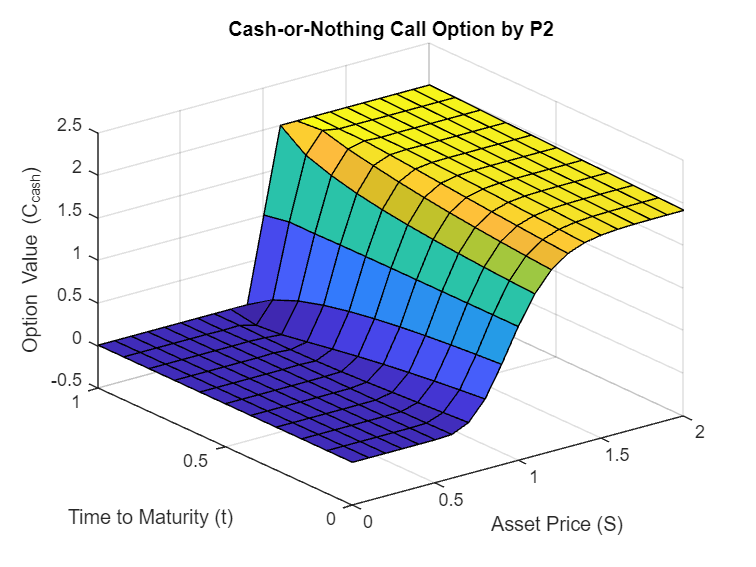

U_exact2 = cash_or_nothing_call_analytical(E, A, r, sigma, T, 2 * L);

x_p2_values = linspace(start_of_the_interval_space, end_of_the_interval_space, number_of_nodes_p2);
t_values = linspace(start_of_the_interval_time, end_of_the_interval_time, number_of_the_elements_time + 1);
[X_P2, T_P2] = meshgrid(x_p2_values, t_values);

figure
surf(X_P2, T_P2, U_P2')
xlabel('Asset Price (S)')
ylabel('Time to Maturity (t)')
zlabel('Option Value (C_{cash})')
title('Cash-or-Nothing Call Option by P2')

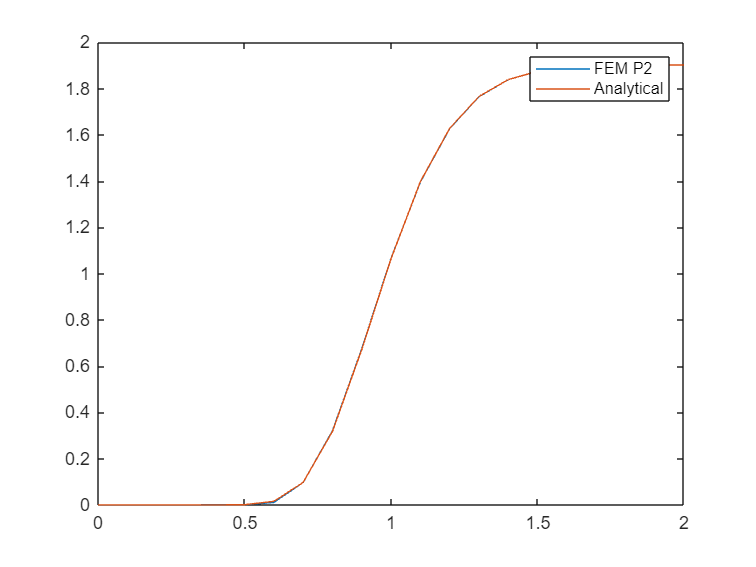

figure;
plot(S_values2(:), U_P2(:, 1));
hold on;
plot(S_values2(:), U_exact2(1, :));
hold off;

legend('FEM P2', 'Analytical');